1.7    （浮点运算）实时脚本

由张志涌编写、修改于 2023.1。

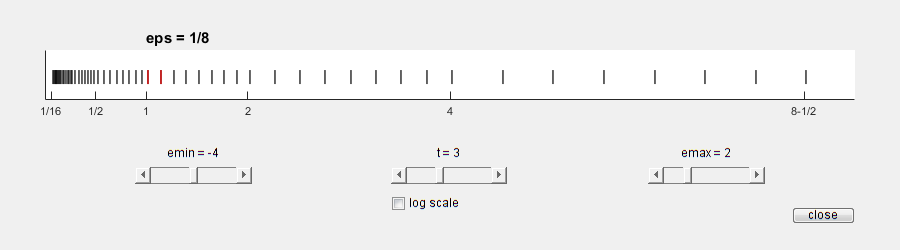

clf
floatgui

eps = 2^(-52)

eps = 2.2204e-16

t = 0.1

t = 0.1000

format hex
t

t =    3fb999999999999a


format hex
phi = (1 + sqrt(5))/2

phi =    3ff9e3779b97f4a8


format long
a = 4/3

a =    1.333333333333333


b = a - 1

b =    0.333333333333333


c = 3*b

c =    1.000000000000000


e = 1 - c

e =      2.220446049250313e-16


phi

phi =    1.618033988749895


[F, E] = log2(phi)

F =    0.809016994374947


E =      1


phi_new = pow2(F,E)

phi_new =    1.618033988749895


format short
A = [17 5; 1.7 0.5]

A =    17.0000    5.0000
    1.7000    0.5000


b = [22; 2.2]

b =    22.0000
    2.2000


x = A\b

x =    -1.2549
    8.6667


mu = 1.7/17;
A(2,:) = A(2,:) - mu*A(1,:)

A =    17.0000    5.0000
         0    0.0000


b(2) = b(2) - mu*b(1)

b =    22.0000
    0.0000


disp(['A(2,2)/eps = ',num2str(A(2,2)/eps)])

A(2,2)/eps = 0.25


disp(['b(2)/eps = ',num2str(b(2)/eps)])

b(2)/eps = 2


x(2) = b(2)/A(2,2);
disp(['x(2) = ',num2str(x(2))])

x(2) = 8


x(1) = (22 - 5*x(2))/17;
disp(['x(1) = ',num2str(x(1))])

x(1) = -1.0588


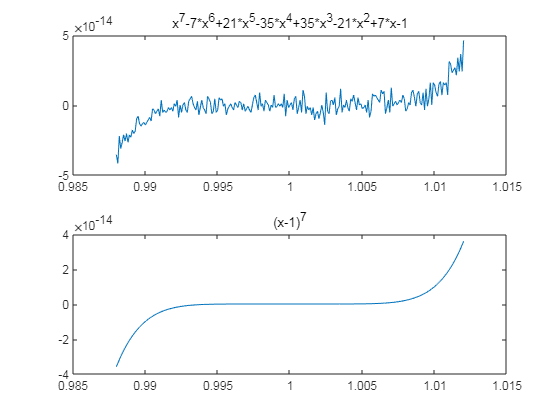

figure
subplot(2,1,1)
x = 0.988:.0001:1.012;
y = x.^7-7*x.^6+21*x.^5-35*x.^4+35*x.^3-21*x.^2+7*x-1;
plot(x,y)
title('x^7-7*x^6+21*x^5-35*x^4+35*x^3-21*x^2+7*x-1')
subplot(2,1,2)
y = (x-1).^7;
plot(x,y)
title('(x-1)^7')